**Test 5**

f = @(x) 1./(1 + x + x.^2);
df = @(x) -(1 + 2*x)./((1 + x + x.^2).^2);

a = -5;
b = 5;
m = 10;
t = 1/2;

a) Sa se reprezinte pe acelasi grafic functia, polinomul de interpolare Lagrange si polinomul de interpolare Hermite

% Nodurile echidistante
x_k = linspace(a, b, m+1);

% Evaluarea functiei f in nodurile x_k
y_k = f(x_k);

% Polinomul de interpolare Lagrange
poly_lagr = @(x) interp_lagrange(x_k, y_k, x);


% Polinomul de interpolare Hermite
poly_hermite = @(x) interp_hermite(x_k, y_k, df, x);

Grafic

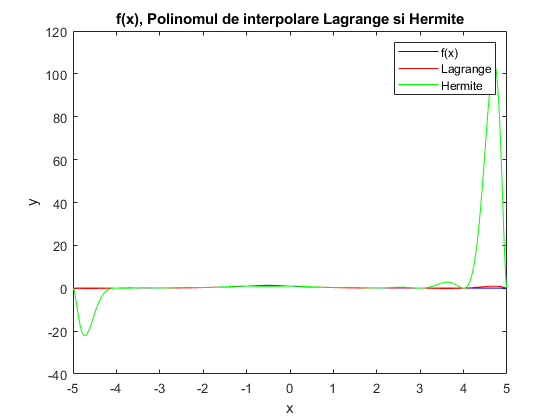

x_plot = linspace(a, b, 1000);
figure;
plot(x_plot, f(x_plot), 'b', x_plot, poly_lagr(x_plot), 'r', x_plot, poly_hermite(x_plot), 'g');
legend('f(x)', 'Lagrange', 'Hermite');
xlabel('x');
ylabel('y');
title('f(x), Polinomul de interpolare Lagrange si Hermite');

b) Sa se aproximeze f(t) folosind toate tipurile de interpolare de la punctul a)

f_t = f(t);
aprox_lagrange = poly_lagr(t);
aprox_hermite = interp_hermite(x_k, y_k, df(x_k), t);

fprintf('f(t) = %.10f\n', f_t);

f(t) = 0.5714285714


fprintf('Aproximare Lagrange: %.10f\n', aprox_lagrange);

Aproximare Lagrange: 0.6716724870


fprintf('Aproximare Hermite: %.10f\n', aprox_hermite(1));

Aproximare Hermite: 0.5545714893


c) Pentru fiecare tip de interpolant precizati eroarea, teoretica - cu ajutorul restului si practic, comparand valoarea functiei returnata de MATLAB cu valorile interpolantului.

error_pract_lagrange = abs(f_t - aprox_lagrange);
error_pract_hermite = abs(f_t - aprox_hermite(1));

fprintf('Eroarea practica Lagrange: %.10f\n', error_pract_lagrange);

Eroarea practica Lagrange: 0.1002439156


fprintf('Eroarea practica Hermite: %.10f\n', error_pract_hermite);

Eroarea practica Hermite: 0.0168570821



% Eroarea teoretica pentru interpolarea Lagrange
est_higher_derivative = estimate_higher_derivative(x_k, y_k, m);
error_theor_lagrange = est_higher_derivative * prod((t - x_k)) / factorial(m+1);

% Eroarea teoretica pentru interpolarea Hermite (estimare)
error_theor_hermite = est_higher_derivative * prod((t - x_k).^2) / factorial(2 * (m+1));

fprintf('Estimarea erorii teoretice Lagrange: %.10f\n', error_theor_lagrange);

Estimarea erorii teoretice Lagrange: -0.0000000007


fprintf('Estimarea erorii teoretice Hermite: %.10f\n', error_theor_hermite);

Estimarea erorii teoretice Hermite: 0.0000000000
